# Simulacije

mat_dir_path = "/home/teo/Documents/Kolegiji/Diplomski_rad/Materijal/MATLAB/Strujni/Mat_files";
picture_path = "/home/teo/Documents/Kolegiji/Diplomski_rad/Materijal/MATLAB/Naponski/Slike";

load (mat_dir_path + "/Samsung_30Q_18650_pack.mat");
load (mat_dir_path + "/VoltaicSystems_P110.mat");

addpath(genpath("Functions"));
addpath("Simulink/");

## Parametri:

% Switching frequency:
boost.f = 1 * 10^5; % [Hz]
boost.T = 1/boost.f;

% Measurement filter cut-off:
boost.mfc = 2000; %[Hz]
boost.Tmfc = 1/(2*pi*boost.mfc);

% Granicni uvjet filter:
boost.Tgf = 1/(pi*1000);

% Maximum duty cycle that can be achieved:
boost.D_max = 1 - pv_data.Umpp/Bat.Ubat_nom; % MPP mode of operation

% Passive elements:
boost.Rt = 1*10^5;
boost.RL = 100 * 10^-3;
boost.Ru = 1;
boost.L = 10 * 10^-6;
boost.Cu = 1500 * 10^-6;
boost.Ci = 1200 * 10^-6;
boost.Cbat = (Bat.Qbat_tot)/(Bat.Ubat_charged - Bat.Ubat_cut_off);

## Fotonapon:

pv_in.G = 800;     %[W/m^2]
pv_in.t = 25;       %[deg]
pv_in.ramp = 1;     %[/]

pv = calc_pv_res("Solar_v2", pv_in);

## Radna tocka:

ccm_op = calc_ccm_op(boost, Bat, pv)

ccm_op = struct with fields:
     Upv0: 5.7000
     Ipv0: 1.4690
      IL0: 1.4690
    Ubat0: 11.5087
       D0: 0.5175
       E0: 4.3294e+04


dcm_op = calc_dcm_op(boost, Bat, pv)

dcm_op = struct with fields:
     Upv0: 5.7000
     Ipv0: 1.4690
      IL0: 1.4690
    Ubat0: 11.5087
       D0: 0.5101
       E0: 4.3294e+04



sim_op = dcm_op;

## Step setup:

% Step input settings:
stepp.step_time = 20 * 10^-3; % [ms]
stepp.sim_time = 50 * 10^-3; % [ms]
% stepp.sim_time = 0.05;

op = calc_dcm_op(boost, Bat, pv);

% Duty cycle:
stepp.D1 = op.D0;
stepp.D2 = stepp.D1 + 0.05;

% Voltage:
stepp.Upv1 = op.Ubat0 - stepp.D1*op.Ubat0 + boost.RL * op.IL0;
stepp.Upv2 = op.Ubat0 - stepp.D2*op.Ubat0 + boost.RL * op.IL0

stepp = struct with fields:
    step_time: 0.0200
     sim_time: 0.0500
           D1: 0.5101
           D2: 0.5601
         Upv1: 5.7856
         Upv2: 5.2101


## CCM TF:

G_ccm = calc_ccm_tf(boost, ccm_op)

G_ccm =
 
         -0.01256 s^2 + 4620 s - 4.316e04
  -----------------------------------------------
  1.026e-05 s^3 + 0.1129 s^2 + 987.7 s + 6.189e05
 
Continuous-time transfer function.
Model Properties



G_dcm = calc_dcm_tf(boost, dcm_op)

G_dcm =
 
       -0.003199 s - 2.728
  ------------------------------
  2.689e-06 s^2 + 3448 s - 6.775
 
Continuous-time transfer function.
Model Properties


## Linearni vs nelinearni:

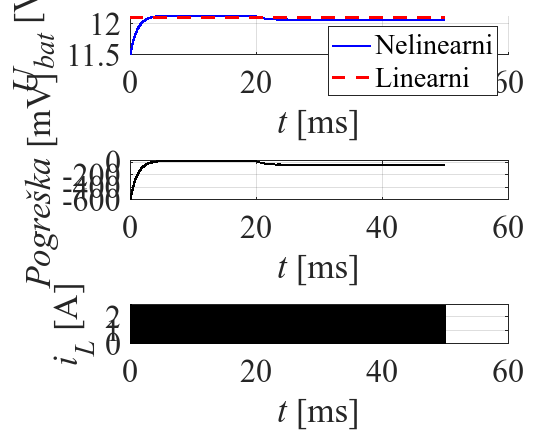

sim_op = dcm_op;

% lin = sim("Simulink/Linearni.slx");

response = sim("Simulink/Nelinearni_realni.slx");

% Extract
IL_nonlin = response.get("IL").Data;
Ubat_nonlin = response.get("Ubat").Data;
Ubat_lin = response.get("Ubat_lin").Data;
t = response.get("Ubat").Time * 1000;  % convert to ms

% % Time period to cut from graph (10 ms)
% t_start = 10;  % [ms]
% idx = t >= t_start;
% 
% % Shorten arrays
% t = t(idx) - t_start;
% IL_nonlin = IL_nonlin(idx);
% Ubat_nonlin = Ubat_nonlin(idx);
% Ubat_lin = Ubat_lin(idx);

% % Set paper properties on the figure
% fig.PaperUnits = 'centimeters';
% fig.PaperSize = [21 29.7];           % width x height in inches
% fig.PaperPosition = [0 0 8 4.5];   % position on paper (fill whole paper)

% for 11 x 9 (W x H)
width_px = round(11/2.54 * 300); % ~1335 pixels
height_px = round(9/2.54 * 300); % ~1146 pixels
% width_px = round(15.52/2.54 * 300); % ~1335 pixels
% height_px = round(7.5/2.54 * 300); % ~1146 pixels

fig = figure('Units','pixels', 'Position', [100 100 width_px height_px]); % W x H

% Plotting a 3 x 1 array of graphs:
layout = tiledlayout(3,1);
layout.TileSpacing = 'compact';
layout.Padding = 'compact';

% Output voltage:
nexttile;
hold on;
plot(t, Ubat_nonlin, 'b', 'LineWidth', 1.5);
plot(t, Ubat_lin, '--r', 'LineWidth', 2.5);
hold off;
xlabel("\it{t}\rm [ms]");
ylabel("\it{U_{bat}}\rm [V]");
legend("Nelinearni", "Linearni");
axis auto;
ax = gca;
ax.FontSize = 24;
ax.FontName = 'Times New Roman';
grid on;

% Error:
nexttile;
error = (Ubat_nonlin - Ubat_lin)*1000;
plot(t, error, 'k', 'LineWidth', 1.5);
ylabel("\it{Pogreška}\rm [mV]");
xlabel("\it{t}\rm [ms]");
ax = gca;
ax.FontSize = 24;
ax.FontName = 'Times New Roman';
grid on;

% Struja zavojnice:
nexttile;
plot(t, IL_nonlin, 'k', 'LineWidth', 1.5);
ylabel("\it{i_L}\rm [A]");
xlabel("\it{t}\rm [ms]");
ax = gca;
ax.FontSize = 24;
ax.FontName = 'Times New Roman';
grid on;

exportgraphics(gcf, picture_path + "/graf_dcm.png", 'Resolution', 300);

## Polovi i nule:

Gz = {G_ccm};

fig = plot_p_and_z(Gz, G_ccm, '$Polovi/Nule$');

Current plot released


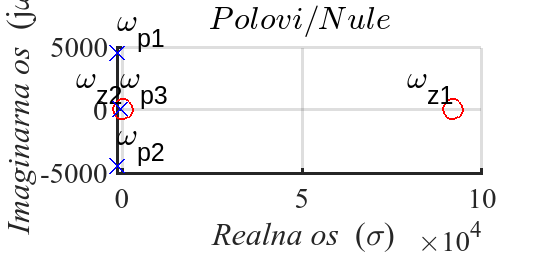

exportgraphics(gcf, picture_path + "/PZ_ccm.png", 'Resolution', 300);

## Radna tocka za Ubat0:

syms Ru Rt RL Ubat0 Upv0 Uoc0 IL0

eq = (Ru+Rt)/(Rt*Ru)*Ubat0^2 - (Uoc0/Ru)*Ubat0 + RL*IL0^2 - Upv0*IL0;


sol = solve(eq == 0, Ubat0)

$$sol = \begin{array}{l} \left(\begin{array}{c} \frac{\mathrm{Rt}\,\left({\mathrm{Uoc}}_{0}+\sigma_{1}\right)}{2\,\left(\mathrm{Rt}+\mathrm{Ru}\right)}\\ \frac{\mathrm{Rt}\,\left({\mathrm{Uoc}}_{0}-\sigma_{1}\right)}{2\,\left(\mathrm{Rt}+\mathrm{Ru}\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\frac{-4\,\mathrm{RL}\,{{\mathrm{IL}}_{0}}^{2}\,{\mathrm{Ru}}^{2}-4\,\mathrm{RL}\,\mathrm{Rt}\,{{\mathrm{IL}}_{0}}^{2}\,\mathrm{Ru}+4\,{\mathrm{Upv}}_{0}\,{\mathrm{IL}}_{0}\,{\mathrm{Ru}}^{2}+4\,\mathrm{Rt}\,{\mathrm{Upv}}_{0}\,{\mathrm{IL}}_{0}\,\mathrm{Ru}+\mathrm{Rt}\,{{\mathrm{Uoc}}_{0}}^{2}}{\mathrm{Rt}}} \end{array}$$

## State space representation CCM:

clear all;

syms s

syms RL L Ipv0 Cu Upv0 Ci T
syms D0 IL0 Ubat0 I10
syms Ru Rt Cbat

% CCM matrices:
A_ccm = sym('a', [4, 4]);
B_ccm = sym('b', [4, 1]);
C_ccm = [0, 0, 1, 0];
D_ccm = 0;
I_ccm = eye(4,4);

subs_list_ccm = {
    A_ccm(1, 1), -RL/L;
    A_ccm(1, 2), 1/L;
    A_ccm(1, 3), (D0-1)/L;
    A_ccm(1, 4), 0;
    A_ccm(2, 1), -1/Cu;
    A_ccm(2, 2), -(Ipv0)/(Cu*Upv0);
    A_ccm(2, 3), 0;
    A_ccm(2, 4), 0;
    A_ccm(3, 1), (1-D0)/Ci;
    A_ccm(3, 2), 0;
    A_ccm(3, 3), -(Ru+Rt)/(Ci*Rt*Ru);
    A_ccm(3, 4), 1/(Ci*Ru);
    A_ccm(4, 1), 0;
    A_ccm(4, 2), 0;
    A_ccm(4, 3), 1/(Cbat*Ru);
    A_ccm(4, 4), -1/(Cbat*Ru);
    B_ccm(1), Ubat0/L;
    B_ccm(2), 0;
    B_ccm(3), -IL0/Ci;
    B_ccm(4), 0;
};

A_ccm = subs(A_ccm, subs_list_ccm(:,1), subs_list_ccm(:,2));
B_ccm = subs(B_ccm, subs_list_ccm(:,1), subs_list_ccm(:,2));

G_ccm_sym = collect(simplify(C_ccm * inv(s * I_ccm - A_ccm)*B_ccm + D_ccm), s)

% G_ccm_lim_sym = collect(simplify(limit(G_ccm_sym, Cbat, inf)))

## TF's DCM:

clear all;

syms s

syms RL L Ipv0 Cu Upv0 Ci T
syms D0 IL0 Ubat0 I10
syms Ru Rt Cbat

% DCM matrices:
A_dcm = sym('a', [3, 3]);
B_dcm = sym('b', [3, 1]);
C_dcm = [0, 1, 0];
D_dcm = 0;
I_dcm = eye(3,3);

subs_list_dcm = {
    A_dcm(1, 1), -1/Cu*((Ubat0^2*D0^2*T)/(2*L*(Ubat0-Upv0)^2) + Ipv0/Upv0);
    A_dcm(1, 2), 1/Cu*(Upv0^2*D0^2*T)/(2*L*(Ubat0-Upv0)^2);
    A_dcm(1, 3), 0;
    A_dcm(2, 1), 1/Ci*(Upv0*Ubat0*D0^2*T)/(2*L*(Ubat0-Upv0)^2);
    A_dcm(2, 2), -1/Ci*((Upv0^3*D0^2*T)/(2*Ubat0*L*(Ubat0-Upv0)^2) + (Ru+Rt)/(Rt*Ru));
    A_dcm(2, 3), 1/Ci*1/Ru;
    A_dcm(3, 1), 0;
    A_dcm(3, 2), 1/(Cbat*Ru);
    A_dcm(3, 3), -1/(Cbat*Ru);
    B_dcm(1), -1/Cu*(Upv0^2*Ubat0*D0^2*T)/(L*(Ubat0-Upv0)^2);
    B_dcm(2), -1/Ci*(Upv0^3*D0^2*T)/(L*(Ubat0-Upv0)^2);
    B_dcm(3), 0;
};

A_dcm = subs(A_dcm, subs_list_dcm(:,1), subs_list_dcm(:,2));
B_dcm = subs(B_dcm, subs_list_dcm(:,1), subs_list_dcm(:,2));

G_dcm_sym = collect(simplify(C_dcm * inv(s * I_dcm - A_dcm)*B_dcm + D_dcm), s)

G_dcm_lim_sym = collect(simplify(limit(G_dcm_sym, Cbat, inf)))


[p, t] = numden(G_dcm_sym);
c = coeffs(expand(p), s);

## Damping:

run ('Parametri_state_space.mlx');

% extrtact num and denum:
[num, den] = numden(G_ccm(2, 1));

% collect coeffs and powers:
den_collct = collect(den, s);
[coeffs_d, powers_d] = coeffs(den_collct, s);
